%butterworth using IIR
clc
clear all
close all
fc=100

fc = 100

fs=1000

fs = 1000

f=50

f = 50

t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


order=4

order = 4

sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))

sgnl =    -0.3444    0.7852    1.9733    1.5585    2.0816    2.3363    2.3550    2.4392    1.7340    1.4937    0.3686   -0.3925   -1.3864   -1.2767   -2.8764   -1.5630   -2.8356   -2.0226   -1.2114   -1.1163   -0.9261    1.0069    1.8068    0.9328    2.3012    3.1902    2.5832    1.1085    1.6245    1.2996    0.1995   -0.7293   -2.1643   -2.0978   -1.9133   -2.8910   -1.5036   -1.3211   -1.1822   -0.4949    0.2276    0.0227    1.5924    2.3513    1.4424    2.3892    1.7582    1.4724    0.9878    0.3114


[b,a]=butter(order,fc/(fs/2),'low')

b =     0.0048    0.0193    0.0289    0.0193    0.0048


a =     1.0000   -2.3695    2.3140   -1.0547    0.1874


filsgnl=filter(b,a,sgnl)

filsgnl =    -0.0017   -0.0068    0.0024    0.0815    0.2912    0.6438    1.0934    1.5655    1.9825    2.2755    2.3898    2.2884    1.9544    1.3998    0.6756   -0.1345   -0.9303   -1.6143   -2.1119   -2.3741   -2.3807   -2.1507   -1.7214   -1.1229   -0.4033    0.3568    1.0843    1.7252    2.2072    2.4498    2.4204    2.1458    1.6679    1.0176    0.2358   -0.5958   -1.3662   -1.9665   -2.3106   -2.3603   -2.1393   -1.7150   -1.1702   -0.5736    0.0407    0.6493    1.2080    1.6596    1.9516    2.0449


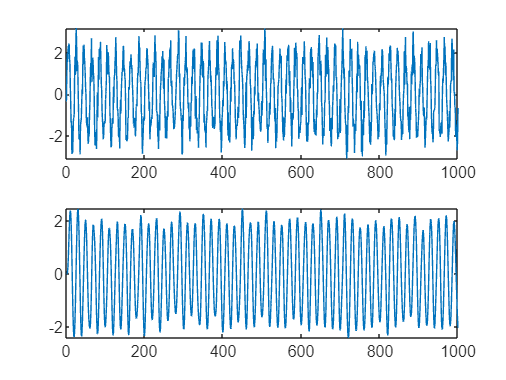

subplot(2,1,1)
plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

%butterworth using FIR
clc
clear all
close all
fc=100

fc = 100

fs=1000

fs = 1000

f=50

f = 50

order=30

order = 30

t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))

sgnl =     0.6468    1.4629    1.2294    2.1714    1.7388    1.5778    2.2432    1.7881    0.9052    0.5291   -0.3965    0.5852   -1.7232   -1.6586   -1.8094   -1.9039   -1.9801   -2.0877   -0.5462   -1.1603   -0.8035   -0.2474    1.8589    1.4326    2.0273    1.2620    1.2546    2.7391    1.0319   -0.0025    0.3734    0.1086   -1.9839   -0.9190   -1.8766   -1.8608   -1.9288   -1.6846   -0.5354   -0.8851    0.6243    0.6722    0.9145    1.9711    1.8117    1.6829    1.3696    2.1427    1.5165    1.2083


b=fir1(order,fc/(fs/2),'low',hamming(order+1))

b =     0.0000    0.0012    0.0028    0.0042    0.0039   -0.0000   -0.0083   -0.0186   -0.0254   -0.0212    0.0000    0.0396    0.0919    0.1451    0.1849    0.1997    0.1849    0.1451    0.0919    0.0396    0.0000   -0.0212   -0.0254   -0.0186   -0.0083   -0.0000    0.0039    0.0042    0.0028    0.0012    0.0000


filsgnl=filter(b,1,sgnl)

filsgnl =     0.0000    0.0008    0.0036    0.0083    0.0148    0.0191    0.0154   -0.0011   -0.0318   -0.0699   -0.0974   -0.0891   -0.0153    0.1435    0.3938    0.7204    1.0877    1.4454    1.7389    1.9214    1.9584    1.8346    1.5531    1.1356    0.6155    0.0384   -0.5453   -1.0836   -1.5271   -1.8373   -1.9863   -1.9581   -1.7513   -1.3830   -0.8820   -0.2954    0.3189    0.8974    1.3782    1.7102    1.8586    1.8111    1.5772    1.1821    0.6684    0.0868   -0.5053   -1.0488   -1.4853   -1.7643


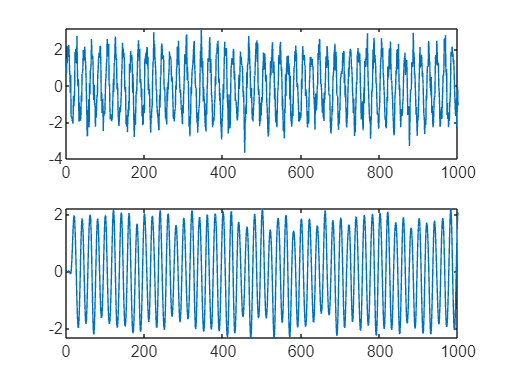

subplot(2,1,1)
plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

%cheby using IIR
clc
clear all
close all
fc=100

fc = 100

fs=1000

fs = 1000

f=50

f = 50

t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


pb=0.4

pb = 0.4000

sb=40

sb = 40

sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))

sgnl =     0.5304    0.8820    1.2567    2.1686    1.1801    1.6105    2.1171    1.7183    1.5907   -0.3052   -0.6038   -1.4201   -2.0453   -1.5033   -1.2631   -2.9806   -2.5584   -1.5831   -1.1288    0.0067    0.9638    0.4977    0.8826    1.5418    2.1720    1.8779    1.8891    1.2420    0.6916    0.3607    0.1573   -0.5105   -1.5872   -1.2039   -2.5295   -2.0014   -2.7205   -1.6515   -0.0745   -1.0811   -0.0534    1.0449    1.0753    1.3252    2.5861    2.0754    3.1115    2.5819    0.6809    0.9158


[n,wn]=cheb1ord(fc/(fs/2),(fc+10)/(fs/2),pb,sb)

n = 15

wn = 0.2000

[b,a]=cheby1(n,pb,wn,"low")

b = 1.0e-07 *

    0.0000    0.0007    0.0046    0.0199    0.0596    0.1311    0.2185    0.2809    0.2809    0.2185    0.1311    0.0596    0.0199    0.0046    0.0007    0.0000


a = 1.0e+03 *

    0.0010   -0.0128    0.0780   -0.2986    0.8034   -1.6097    2.4801   -2.9912    2.8471   -2.1383    1.2568   -0.5677    0.1908   -0.0450    0.0067   -0.0005


filsgnl=filter(b,a,sgnl)

filsgnl =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0008    0.0020    0.0046    0.0098    0.0198    0.0376    0.0673    0.1143    0.1843    0.2829    0.4137    0.5766    0.7659    0.9686    1.1638    1.3231    1.4135    1.4019    1.2608    0.9756    0.5497    0.0089   -0.5992   -1.2084   -1.7429   -2.1284   -2.3045   -2.2359   -1.9204   -1.3907   -0.7101    0.0365    0.7569    1.3653    1.7955    2.0093    1.9988    1.7842    1.4062


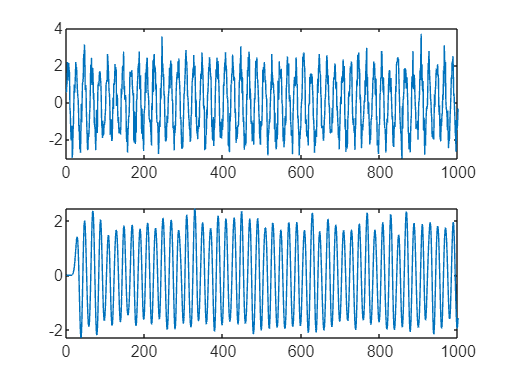

subplot(2,1,1)
plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

% cheby using FIR
clc
clear all
close all
fc=100

fc = 100

fs=1000

fs = 1000

f=50

f = 50

t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))

sgnl =     0.4179    1.4579    1.5521    1.4941    1.4887    0.9689    2.8594    2.2293    1.0320    0.7127   -0.5058   -1.0031   -1.0267   -0.9979   -1.7726   -1.1492   -1.6843   -2.1077   -1.6622   -0.3475   -0.7101    0.7408    0.7606    2.5503    1.9211    2.1504    0.9436    1.2037    0.7275    0.9918    0.6054   -0.6981   -1.0226   -1.6820   -1.9245   -2.2952   -2.4182   -1.4590   -0.9179   -0.2530    0.1744    1.0788    0.9151    1.4271    1.8748    2.0037    1.9313    0.9379    0.8348    0.5892


pb=0.4

pb = 0.4000

order=40

order = 40

sb=40

sb = 40

coeff=fir1(order,fc/(fs/2),'low',chebwin(order+1,pb))

coeff =    -0.0000   -0.0102   -0.0175   -0.0185   -0.0122    0.0000    0.0140    0.0243    0.0264    0.0178   -0.0000   -0.0218   -0.0397   -0.0454   -0.0327    0.0000    0.0491    0.1059    0.1589    0.1965    0.2100    0.1965    0.1589    0.1059    0.0491    0.0000   -0.0327   -0.0454   -0.0397   -0.0218   -0.0000    0.0178    0.0264    0.0243    0.0140    0.0000   -0.0122   -0.0185   -0.0175   -0.0102   -0.0000


filsgnl=filter(coeff,1,sgnl)

filsgnl =    -0.0000   -0.0043   -0.0222   -0.0491   -0.0746   -0.0879   -0.0768   -0.0615   -0.0408   -0.0099    0.0225    0.0541    0.0743    0.0709    0.0404    0.0019   -0.0272   -0.0080    0.0970    0.3041    0.5995    0.9652    1.3435    1.6799    1.9003    1.9693    1.8635    1.5974    1.1890    0.6771    0.1012   -0.4879   -1.0283   -1.4718   -1.7745   -1.9073   -1.8529   -1.6120   -1.2137   -0.6969   -0.1126    0.4808    1.0142    1.4466    1.7399    1.8642    1.8089    1.5537    1.1341    0.5963


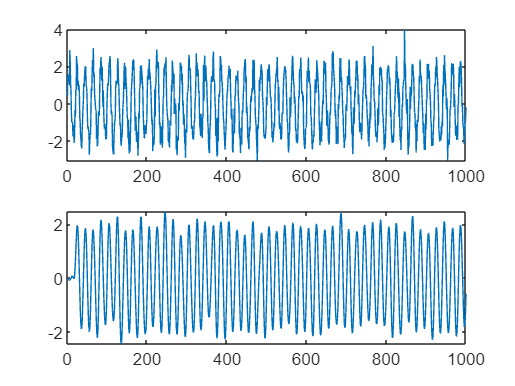

subplot(2,1,1)
plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

% butterworth using FIR
%butterworth using IIR
% chebyshev using FIR
%chebyshev using IIR

clc
clear all
close all
fc=100
fs=1000
f=50
t=0:1/fs:1-1/fs
sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))
order=4
[b,a]=butter(order,fc/(fs/2),'low')
filsgnl=filter(b,a,sgnl)
subplot(2,1,1)
plot(sgnl)

subplot(2,1,2)
plot(filsgnl)


% Butterworth using FIR
clc
clear all
close all
fc=100
fs=1000
f=50
t=0:1/fs:1-1/fs
order=40
sgnl=2*sin(2*pi*f*t)+randn(size(t))
[b,a]=fir1(order,fc/(fs/2),hamming(order+1))
filsgnl=filter(b,a,sgnl)

subplot(2,1,1)
plot(sgnl)

subplot(2,1,2)
plot(filsgnl)


%chebyshev using IIR
clc
clear all
close all
fc=100
fs=1000
f=50
t=0:1/fs:1-1/fs
pb=0.4
sb=40
sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))
[n,wn]=cheb1ord(order,fc/(fs/2),(fc+10)/(fs/2),pb,sb)
[b,a]=cheby1(n,pb,wn,"low")
filsgnl=filter(b,a,sgnl)
subplot(2,1,1)
plot(sgnl)

subplot(2,1,2)
plot(filsgnl)

%chebyshev using FIR
clc
clear all
close all
fs=1000
fc=100
f=50
t=0:1/fs:1-1/fs
sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))
coeff=fir1(order,fc/(fs/2),'low',chebwin(order+1,pb))
filsgnl=filter(coeff,1,sgnl)
subplot(2,1,1)
plot(sgnl)

subplot(2,1,2)
plot(filsgnl)